student.name = {'Enyuku pius'; 'Hafizah Khadijah Musa'; 'Rubangakene Jonathan'; 'Kisolo Owen Sam'; 'Mugusha Job'};
student.tribe ={'ateso';'acholi';'luo';'baganda';'baganda'};
student.residence = {'hostel';'hall';'hostel';'hostel';'hostel'};
student.friends ={'anshe';'hannah';'mark';'steve';'mark'};
student.age ={21;21;22;22;21};
student.course ={'BEM';'BEM';'BEM';'BEM';'BEM'};
BEM_students = table(student.name, student.tribe, student.residence,student.friends,student.age,student.course);
'varibleNames',{'Name','Tribe','residence','friends','age','course'}

ans = 'varibleNames'

ans = 1×6 cell array
    {'Name'}    {'Tribe'}    {'residence'}    {'friends'}    {'age'}    {'course'}


ourgroup = readtable('C:\Users\piuse\OneDrive\Desktop\group work\GROUP 8.xlsx')

ourgroup = 5×8 table
            FULLNAME                    REGNO               TRIBE       RESIDENCE      FRIENDS      AGE    GROUPNAME    GROUPNUMBER
    _________________________    ____________________    ___________    __________    __________    ___    _________    ___________

    {'ENYUKU PIUS'          }    {'BU/UP/2025/4638' }    {'ATESO'  }    {'HOSTEL'}    {'ANSHE' }    21     {'ONE'  }         1     
    {'MUGUSHA JOB'          }    {'BU/UP/2025/05719'}    {'BUGANDA'}    {'HOSTEL'}    {'MARK'  }    22     {'TWO'  }         2     
    {'RUBANGAKENE JONATHAN' }    {'BU/UP/2025/1994' }    {'LUO'    }    {'HOSTEL'}    {'STEVE' }    21     {'THREE'}         3     
    {'KISOLO OWEN SAM'      }    {'BU/UP/2025/

data = readtable('C:\Users\piuse\OneDrive\Desktop\group work\GROUP 8.xlsx')

data = 5×8 table
            FULLNAME                    REGNO               TRIBE       RESIDENCE      FRIENDS      AGE    GROUPNAME    GROUPNUMBER
    _________________________    ____________________    ___________    __________    __________    ___    _________    ___________

    {'ENYUKU PIUS'          }    {'BU/UP/2025/4638' }    {'ATESO'  }    {'HOSTEL'}    {'ANSHE' }    21     {'ONE'  }         1     
    {'MUGUSHA JOB'          }    {'BU/UP/2025/05719'}    {'BUGANDA'}    {'HOSTEL'}    {'MARK'  }    22     {'TWO'  }         2     
    {'RUBANGAKENE JONATHAN' }    {'BU/UP/2025/1994' }    {'LUO'    }    {'HOSTEL'}    {'STEVE' }    21     {'THREE'}         3     
    {'KISOLO OWEN SAM'      }    {'BU/UP/2025/0587

output = data(:,{'GROUPNAME','GROUPNUMBER'});
writetable(output,'student output.xlsx','sheet','groupinformation');
disp('infromation successfully exported!')

infromation successfully exported!


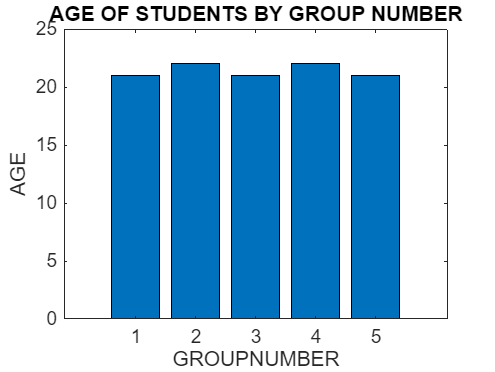

figure;
bar(data.GROUPNUMBER, data.AGE);
xlabel('GROUPNUMBER');
ylabel('AGE');
title('AGE OF STUDENTS BY GROUP NUMBER');
saveas(gcf,'student age plot.png')

n = input('enter number of students:');
sem = input('enter number of semesters:');
coures = input('enter number of courses:');
for i = 1:n
fprintf('\nstudent%d\n',i);
totalpoints = 0;
totalcredits = 0;
for s = 1:sem
fprintf('\nstudent%d\n',s);
semesterpoints=0;
semestercredits=0;
for c =1:coures
mark = input(sprintf('enter mark for course %d;',c));
credit = input(sprintf('enter  credit unit for course %d;', c));
if mark >= 80
    gp=5;
elseif mark >= 75
    gp=4.5;
elseif mark >= 70
    gp=4;
elseif mark >= 65
    gp=3.5;
elseif mark >= 60
    gp=3;
elseif mark >= 55
    gp=2.5;
elseif mark >= 50
    gp = 2;
elseif mark >= 45
    gp=1.5;
elseif mark >= 40
    gp = 1;
else
    gp=0;
end
 semesterpoints = semesterpoints + (gp * credit);
semestercredits = semestercredits + gp;
end
GPA = semesterpoints / semestercredits;
fprintf('GPA for semester %d = %.2f\n',s,GPA);
totalpoints = totalpoints + semesterpoints;
totalcredits =totalcredits + semestercredits
end
CGA = totalpoints/totalcredits;
fprintf('\nstudent %d CGA = %.2f\n',i,CGA);
end
